close all
clear all
colors=npg(10); % Ten basic colors

%% Input Area

maindir='\\Artemis-pc\e\Data\2023-08-30\';%数据来源路径

plotnumber=1;%是否画原子数
plotradius=0;%是否画原子团半径
plotODsum=1;%是否画OD求和
plotSNRGain=0;%是否画SNR Gain
plotnoise_FR=0;%是否画Fringe removal后的noise OD
plotprecession=1;%是否画进动

first=174;%第一个文件夹序号
last=216;%最后一个文件夹序号

%设置横坐标公式为:xaxis=(first-1:last-1)*coeff+intercept;
intercept=0.2;%第一组数据的自变量`
coeff=0.005;%各组数据自变量间隔

% setXlabel='Ramsey Interrogation time ms';%横坐标label
% setXlabel='ROT pulse us';%横坐标label
% setXlabel='BusODT Hold s';%横坐标label
% setXlabel='Precession time ms';%横坐标label
% setXlabel='556 Freq V';%横坐标label
% setXlabel='399 Freq V';%横坐标label
% setXlabel='MOT Ramp s';%横坐标label
% setXlabel='Spin echo time s';%横坐标label
setXlabel='Polar pulse us';%横坐标label
%% read data
datalength=last-first+1;
xaxis=(0:last-first)*coeff+intercept;
%xaxis=[0:50:500 600:100:1000 1500 2000 3000 5000];

% Preallocation
numberofatoms1=zeros(datalength,1);
noise_OD=zeros(datalength,1);
countperpixel=zeros(datalength,1);

ODsum1=zeros(datalength,1);
ODsum2=zeros(datalength,1);
ODsum3=zeros(datalength,1);
ODsum4=zeros(datalength,1);
ODsum5=zeros(datalength,1);
ODsum6=zeros(datalength,1);


numberofatoms2=zeros(datalength,1);
radius=zeros(datalength,1);
noise_FR=zeros(datalength,1);
SNRGain=zeros(datalength,1);
Timelist=datetime(zeros(datalength,6));

tic
parfor i=1:datalength % parallel computing
    filestr=[maindir,'Abs-',num2str(i+first-1),'\Output.txt'];
    filestr;
    datafile=fopen(filestr);
    data_out=textscan(datafile,'%f');
    totaldata=data_out{1};
    fclose(datafile);

    filestr_time=[maindir,'Abs-',num2str(i+first-1),'\time.txt'];
    time_hd=fopen(filestr_time);
    data_time=textscan(time_hd,'%s %s');
    Timelist(i)=datetime([cell2mat(data_time{1,1}),' ',cell2mat(data_time{1,2})],'InputFormat','yyyy-MM-dd HH:mm:ss'); %转成时间序列
    fclose(time_hd);


    numberofatoms1(i)=totaldata(8);
    noise_OD(i)=totaldata(9);
    countperpixel(i)=totaldata(10);
    radius(i)=totaldata(11);
    ODsum1(i)=totaldata(12);
    noise_FR(i)=totaldata(13);
    SNRGain(i)=totaldata(14);

    %只拍摄了一张原子照片时注释掉
    try
        numberofatoms2(i)=totaldata(15);
        ODsum2(i)=totaldata(19);
    catch

    end

    try
        ODsum3(i)=totaldata(26);
        ODsum4(i)=totaldata(33);
        ODsum5(i)=totaldata(40);
        ODsum6(i)=totaldata(47);
    catch

    end

    %     % 用于处理 2022 0814 之前的的数据
    %     numberofatoms1(i+1-first)=totaldata(1);
    %     noise_OD(i+1-first)=totaldata(2);
    %     countperpixel(i+1-first)=totaldata(3);
    %     radius(i+1-first)=totaldata(4);
    %     ODsum1(i+1-first)=totaldata(5);
    %     noise_FR(i+1-first)=totaldata(6);
    %     SNRGain(i+1-first)=totaldata(7);
    %
    %     %只拍摄了一张原子照片时注释掉
    %     numberofatoms2(i+1-first)=totaldata(8);
    %     ODsum2(i+1-first)=totaldata(12);

end
toc

历时 0.610630 秒。


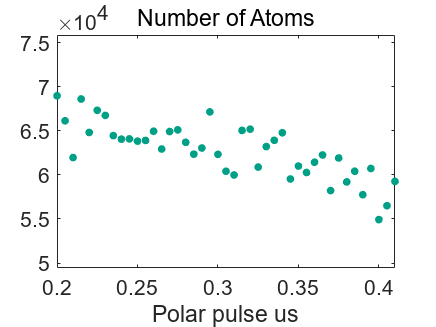




parfor i=1:datalength % parallel computing
    filestr=[maindir,'Abs-',num2str(i+first-1),'\position.txt'];
    filestr;
    datafile=fopen(filestr);
    data_out=textscan(datafile,'%f');
    totaldata=data_out{1};
    fclose(datafile);
%     xposition(i)=totaldata(5);
%     yposition(i)=totaldata(6);
xposition(i)=totaldata(3);
    yposition(i)=totaldata(4);

 

end
%% plot number of atoms
if plotnumber==1
    h1=figure('Name','Number of Atoms');
    plot(xaxis,numberofatoms1,'.','Color',colors(3,:),'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(numberofatoms1)*0.9 max(numberofatoms1)*1.1])
    title('Number of Atoms');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h1,[maindir,'Abs-',num2str(last),'\Numberofatoms.png'])
end

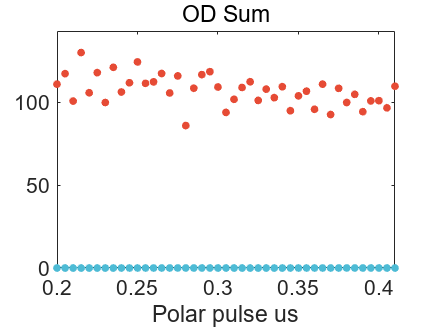

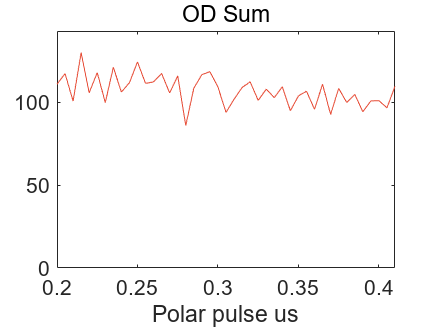

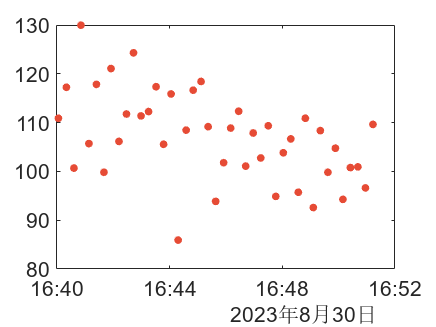

%% plot ODsum
if plotODsum==1
    h2=figure('Name','OD Sum');
    plot(xaxis,ODsum1,'.','Color',colors(1,:),'MarkerSize',20);
    hold on
    plot(xaxis,ODsum2,'.','Color',colors(2,:),'MarkerSize',20);
    axis([min(xaxis) max(xaxis) 0 max(ODsum1)*1.1])
    title('OD Sum');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h2,[maindir,'Abs-',num2str(last),'\ODsum.png'])

    h2_0=figure('Name','OD Sum 1+2');
    ODsum12=ODsum1+ODsum2;
    plot(xaxis,ODsum12,'-','Color',colors(1,:),'MarkerSize',20);
    hold on
    axis([min(xaxis) max(xaxis) 0 max(ODsum1)*1.1])
    title('OD Sum');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
    saveas(h2_0,[maindir,'Abs-',num2str(last),'\ODsum12.png'])

    %% Plot time
    figure
    h3_0=plot(Timelist,ODsum1,'.','Color',colors(1,:),'MarkerSize',20);
    grid off
    set(gca,'FontSize',16)
    saveas(h3_0,[maindir,'Abs-',num2str(last),'\time.png'])

end

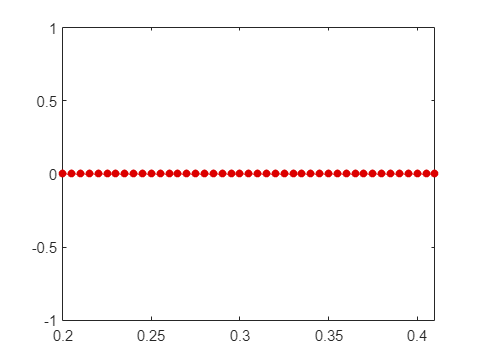

错误使用 matlab.graphics.axis.Axes/set
值必须是数值类型的 1x2 向量，其中第二个元素大于第一个元素或为 Inf。

出错 axis>LocSetLimits (第 293 行)
    set(ax,...

出错 axis (第 114 行)
                LocSetLimits(ax(j),cur_arg,names);

%% plot radius
if plotradius==1
    h3=figure('Name','Radius');
    plot(xaxis,radius,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(radius)*0.9 max(radius)*1.1])
    title('Radius');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end
%% plot SNRGain
if plotSNRGain==1
    h4=figure('Name','SNRGain');
    plot(xaxis,SNRGain,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(SNRGain)*0.9 max(SNRGain)*1.1])
    title('SNR Gain');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end
%% plot noise_FR
if plotnoise_FR==1
    h5=figure('Name','Noise_FR');
    plot(xaxis,noise_FR,'.','Color',[0 98 132]./255.0,'MarkerSize',20);
    axis([min(xaxis) max(xaxis) min(noise_FR)*0.9 max(noise_FR)*1.1])
    title('Noise FR');
    xlabel(setXlabel);
    grid off
    set(gca,'FontSize',16)
end
%% plot precession
if plotprecession==1
    %relativeOD=ODsum1;
    relativeOD=ODsum2./ODsum1;
    %relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
    s1=ODsum1;
    s2=ODsum2;
    
%     relativeOD=ODsum3./ODsum2;

%     s1=(ODsum1+ODsum3+ODsum5)./3;
%     s2=(ODsum2+ODsum4+ODsum6)./3;
%     relativeOD=(s1-s2)./(s1+s2);



    h6=figure('Name','Precession');
    plot(xaxis,relativeOD,'.-','Color',colors(8,:),'MarkerSize',16);
    %axis([min(xaxis) max(xaxis) -1 1])
    %axis([min(xaxis) max(xaxis) (min(relativeOD)-0.1)*0 max(relativeOD)+0.1])
    axis([min(xaxis) max(xaxis) min(relativeOD)*0.9 max(relativeOD)*1.1])
    title(' ');
    xlabel(setXlabel);
    ylabel('OD_2/OD_1')
    %ylabel('OD_1')
    %ylabel('S_z')
    grid off
    set(gca,'FontSize',16)
    saveas(h6,[maindir,'Abs-',num2str(last),'\precession.png'])


    %relativeOD_2=ODsum2./ODsum1;
    relativeOD_2=ODsum1./ODsum2;
    %relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
    h7=figure('Name','ODsum2 versus OD sum1');
    plot(xaxis,relativeOD_2,'.','Color',colors(8,:),'MarkerSize',16);
    axis([min(xaxis) max(xaxis) 0.6 1.2])
    title(' ');
    xlabel(setXlabel);
    ylabel('S_z')
    grid off
    set(gca,'FontSize',16)
    saveas(h7,[maindir,'Abs-',num2str(last),'\population.png'])



end



%% plot population
% 
% try
%     population=(ODsum1+ODsum2)./ODsum3;
%     h8=figure('Name','Population_All');
%     plot(xaxis,population,'.','Color',colors(8,:),'MarkerSize',16);
%     axis([min(xaxis) max(xaxis) 0 1])
%     title(' ');
%     xlabel(setXlabel);
%     ylabel('Population')
%     grid off
%     set(gca,'FontSize',16)
%     saveas(h8,[maindir,'Abs-',num2str(last),'\population_all.png'])
% 
%     relativeOD_3=ODsum3./ODsum2;
%     %relativeOD=ODsum1./ODsum2;
%     %relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
%     h9=figure('Name','ODsum3 versus OD sum2');
%     plot(xaxis,relativeOD_3,'.','Color',colors(8,:),'MarkerSize',16);
%     axis([min(xaxis) max(xaxis) 0.6 1.2])
%     title(' ');
%     xlabel(setXlabel);
%     ylabel('S_z')
%     grid off
%     set(gca,'FontSize',16)
%     saveas(h9,[maindir,'Abs-',num2str(last),'\population_loss.png'])
% 
%     relativeOD_4=ODsum3./(ODsum2+ODsum1).*2;
%     %relativeOD=ODsum1./ODsum2;
%     %relativeOD=(ODsum1-ODsum2)./(ODsum1+ODsum2);
%     h9=figure('Name','ODsum3 versus ODsum2+ODsum1');
%     plot(xaxis,relativeOD_4,'.','Color',colors(8,:),'MarkerSize',16);
%     axis([min(xaxis) max(xaxis) 0.6 1.2])
%     title(' ');
%     xlabel(setXlabel);
%     ylabel('S_z')
%     grid off
%     set(gca,'FontSize',16)
%     saveas(h9,[maindir,'Abs-',num2str(last),'\population_loss.png'])
% 
% catch
%     disp('Failed to plot population')
% end
% 


%% Save results

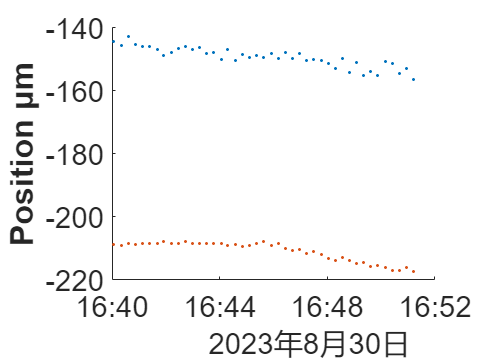

figure;hold on;
plot(Timelist,(75-xposition)*6.5,'.');
plot(Timelist,(75-yposition)*6.5,'.');
ylabel('Position μm','FontWeight','bold')
set(gca,'fontsize',20)

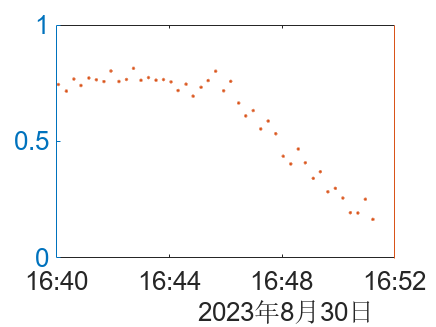

%yticks([-10:2:5])

Timelist.Format="MM-dd HH:mm";
%% 设置导入选项并导入数据
opts = delimitedTextImportOptions("NumVariables", 10);

% 指定范围和分隔符
opts.DataLines = [5, Inf];
opts.Delimiter = ",";

% 指定列名称和类型
opts.VariableNames = ["Var1", "Var2", "Var3", "Var4", "Var5", "time", "temp", "Var8", "Var9", "Var10"];
opts.SelectedVariableNames = ["time", "temp"];
opts.VariableTypes = ["string", "string", "string", "string", "string", "datetime", "double", "string", "string", "string"];

% 指定文件级属性
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 指定变量属性
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var8", "Var9", "Var10"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var1", "Var2", "Var3", "Var4", "Var5", "Var8", "Var9", "Var10"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "time", "InputFormat", "yyyy/MM/dd HH:mm");

% 导入数据
tbl = readtable("C:\Users\USTC\Downloads\2023-06-27_15_38_influxdb_data.csv", opts);

%% 转换为输出类型
time = tbl.time;
temp = tbl.temp;

%% 清除临时变量
clear opts tbl
time.Format="MM-dd HH:mm";

figure;
% yyaxis left
% l1=plot(time,temp);
% l1.LineWidth=1.5;
% ylabel('Temp ℃','FontWeight','bold','Position',[0.37,28.6,-1])

% yyaxis right
% l2=plot(Timelist,(75-yposition)*6.5/2.5);
% l2.LineWidth=1.5;
% ylabel('Position μm','rotation',270,'FontWeight','bold'...
%     ,'Position',[3.15,-2.5,-1])
% yticks([-10:2:5])

yyaxis right
l2=plot(Timelist,(75-yposition)*6.5,'.');
l2.LineWidth=1.5;
ylabel('Position μm','rotation',270,'FontWeight','bold'...
    ,'Position',[3.15,-2.5,-1])
yticks([-10:2:5])

set(gca,'fontsize',20)


clear main_dir_0
save([maindir,'Abs-',num2str(last),'\result.mat'])
save([maindir,'Abs-',num2str(last),'\population.mat'],"s1","s2")


